# Filtrace ve spektru

Vaším úkolem je v audiosignálu **signal.wav** identifikovat rušivý monofrekvenční šum (tón), odstranit tento šum pomocí filtrace ve spektru a odpovědět na otázky.

## Načtení signálu

Načtěte signál (pozn. amplituda WAV je ve Voltech).



%signal si muzete prehrat se sluchátky pomocí funkce soundsc(signal,fs) 
%soundsc()
[y, fs] = audioread("signal.wav");
%soundsc(y,fs)
N = length(y);
T = N/fs

T = 5.2320

Ppuv = 1/N*sum(abs(y).^2)

Ppuv = 0.0150

## Spektrální analýza

Spočtěte frekvenční spektrum signálu a zobrazte jeho magnitudovou část + popište osy.

Y = 1/N*fft(y);
t = linspace(0,(N-1)/fs,N);
f = linspace(0,fs -fs/N,N)

f = 1.0e+04 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009


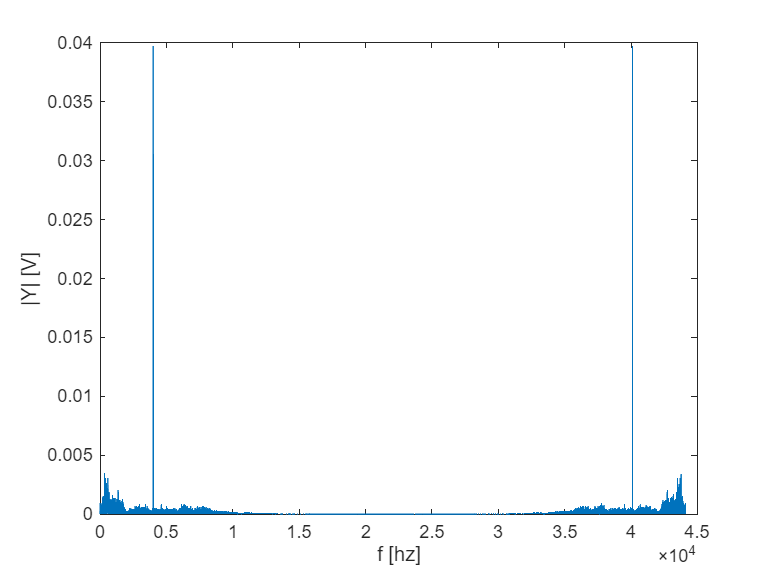

figure
plot(f,abs(Y))
xlabel('f [hz]')
ylabel('|Y| [V]')

Identifikujte frekvenční komponentu monofrekvenčního šumu ($f_{\textrm{noise}}$). Frekvenci určete s přesností na jedno desetinné místo.

k = 0:1:N;
k(abs(Y)>0.01)

ans =        20928      209804


fnoise = f(abs(Y)>0.01)

fnoise = 1.0e+04 *

    0.4000    4.0100


## Filtrace ve spektru

Odstraňte monofrekvenční šum ve spektrální oblasti $f_{\textrm{noise}}$$\pm 100\;\textrm{Hz}$ a převeďte signál zpět do časové oblasti.

idx = (f > fnoise(1)-100) & (f < fnoise(1)+100);
Y(idx)=0;

idx = (f > fnoise(2)-100) & (f < fnoise(2)+100);
Y(idx)=0;

## Zobrazení spektra filtrovaneho signálu

Zobrazte spektrum (spektrogram) signalu.

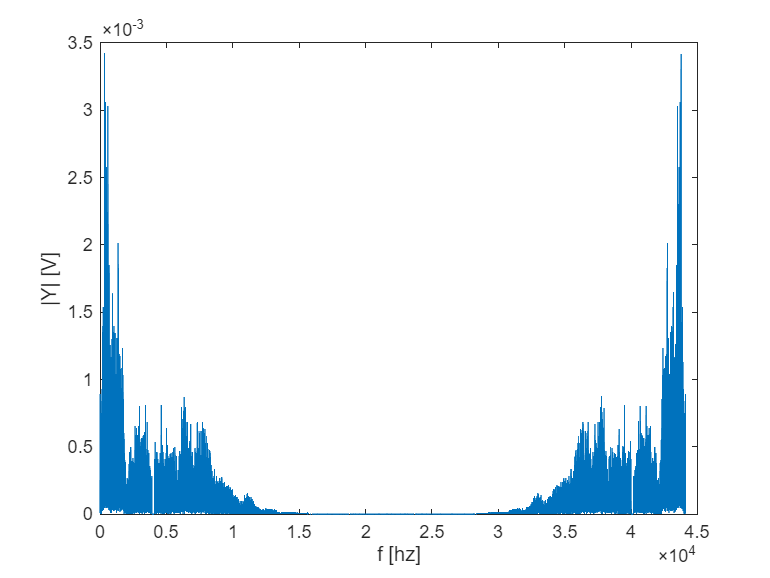

figure
plot(f,abs(Y))
xlabel('f [hz]')
ylabel('|Y| [V]')

y = N*ifft(Y);
Pfilt = 1/N*sum(abs(y).^2)

Pfilt = 0.0118

100 - Pfilt/Ppuv *100

ans = 21.8030

%signal si muzete prehrat pomoci funkce soundsc()
soundsc(y,fs)

## Odpovězte na otázky

Jak dlouhý je signál v sekundách? - Nezapomňte je napsat do Moodlu!!!!

5

ans = 5

Jaký je výkon původního signálu? $P=\frac{1}{N}\sum_n {y\left\lbrack n\right\rbrack }^2$  

0.015

ans = 0.0150

Na jaké frekvenci se nachází monofrekvenční šum?

4000.0

ans = 4000

Jaké indexy spektrálních čar odpovídají frekvenci hledaného šumu?

%20928  209804

O kolik procent se snížil **výkon signálu po filtraci** oproti původnímu signálu?

21.80

ans = 21.8000